clc
clear
close all


## Data loading

cd /Users/finne/Desktop/Kaffee/Kanal
load Pore.mat
Pore_skel = bwskel(Pore);

## Graph for Coffee puck

cd /Users/finne/Desktop/Kaffee/Kanal/Skel2Graph

[A,node,link] = Skel2Graph3D(Pore_skel,5); % This function is from [Original Repo](https://github.com/phi-max/skel2graph3d-matlab/blob/master/Skel2Graph3D.m)


% total length of network
wl = sum(cellfun('length',{node.links}));

w = size(Pore_skel,1);
l = size(Pore_skel,2);
h = size(Pore_skel,3);

skel2 = Graph2Skel3D(node,link,w,l,h);  % This function is from [Original Repo](https://github.com/phi-max/skel2graph3d-matlab/blob/master/Skel2Graph3D.m)
[A2,node2,link2] = Skel2Graph3D(skel2,5);

% calculate new total length of network
wl_new = sum(cellfun('length',{node2.links}));

% iterate the same steps until network length not changed 
while(wl_new~=wl)

    wl = wl_new;   
    
     skel2 = Graph2Skel3D(node2,link2,w,l,h);
     [A2,node2,link2] = Skel2Graph3D(skel2,5);

     wl_new = sum(cellfun('length',{node2.links}));

end

## Branch Segmention

% Watershed

Skel_Branch_point = bwmorph3(skel2,"branchpoints");
Skel_Branch = skel2-Skel_Branch_point ;
dist = bwdist(~Pore);
g = imimposemin(-dist,Skel_Branch,26);
Lm = watershed(g,26);
Pore_16 = uint16(Pore);

Branch = Lm.*Pore_16;
Branch_stat = regionprops3(Branch,'Volume','Image','SurfaceArea','VoxelIdxList','VoxelList');
Branch_stat.Sv = (Branch_stat.SurfaceArea.*6.5^2)./(Branch_stat.Volume.*6.5^3).*1e6;

## Skel label

% Skel label from Watershed 
Skel_label = uint16(skel2).* Branch;

## Tortousity & Sv


% Initialize parameter matrix
Para = zeros([w*h*l], 2);

for i = 1:length(link2)
    node_1 = link2(i).n1;
    node_2 = link2(i).n2;
    points = link2(i).point;
    num_points = length(link2(i).point);

    [x, y, z] = ind2sub([w, l, h], points);
    values = Skel_label(points);
    region_idx = unique(values);
    region_idx(region_idx == 0) = [];
    Sv = Branch_stat.Sv(region_idx);

    dx = diff(x); % Difference vector in x direction
    dy = diff(y); % Difference vector in y direction
    dz = diff(z); % Difference vector in z direction
    distance_matrix = sqrt(dx.^2 + dy.^2 + dz.^2);
    distance = sqrt((x(end)-x(1))^2 + (y(end)-y(1))^2 + (z(end)-z(1))^2);
    tortuosity = sum(distance_matrix) / distance;

    Para(points,1) = tortuosity;
    Para(points,2) = Sv;
end


% Reshape data into 3D arrays
Tou_3D = reshape(Para(:,1), w, l, h);
Sv_3D = reshape(Para(:,2), w, l, h);
reshaped_Tou = reshape(Tou_3D, [], h); 
Tou_z = (sum(reshaped_Tou,1) ./ sum(reshaped_Tou ~= 0, 1))';

reshaped_Sv = reshape(Sv_3D, [], h); 
Sv_z = (sum(reshaped_Sv,1) ./ sum(reshaped_Sv ~= 0, 1))';

% Compute mean values
mean(Sv_z)

ans = 1.0708e+05

mean(Tou_z)

ans = 1.3727


reshaped_D = reshape(dist, [], h);
Radius_z = (sum(reshaped_D,1) ./ sum(reshaped_D ~= 0, 1))';


% Compute porosity
porosity = zeros(size(Pore,3),1);
for i = 1:size(Pore,3)
    porosity(i) = nnz(Pore(:,:,i)) / 7.8540e+05;
end

% Compute permeability
k = (porosity.^3) ./ (2 .* (Tou_z.^2) .* ((Sv_z.^2) .* ((1 - porosity).^2)));
k2 = ((83.4e-6)^2).* ((mean(porosity))^3)/ 180/ ((1 - (mean(porosity))^2));
mean(k)

ans = 4.2799e-14

k2

k2 = 5.4260e-14

## Pressure Loss

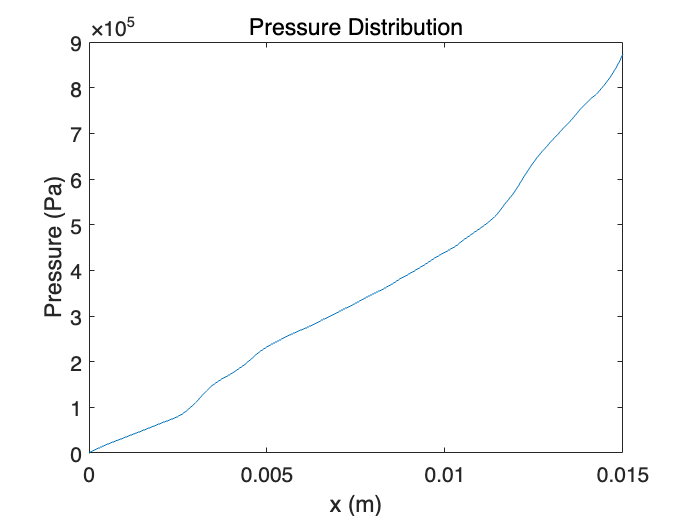

% Define area and compute flow rate q
Area = (58e-3 / 2)^2 * pi;
q = 2e-6 ./ (Area .* porosity);

mu = 0.315e-3; % Viscosity
x = linspace(0, 15e-3, h); % Discrete spatial coordinates

% Compute cumulative integral of 1/k(x)
inv_k = 1 ./ k;
integral_cumulative = cumtrapz(x, inv_k .* mu .* q);

% Plot pressure distribution
figure;
plot(x, integral_cumulative);
xlabel('x (m)');
ylabel('Pressure (Pa)');
title('Pressure Distribution');

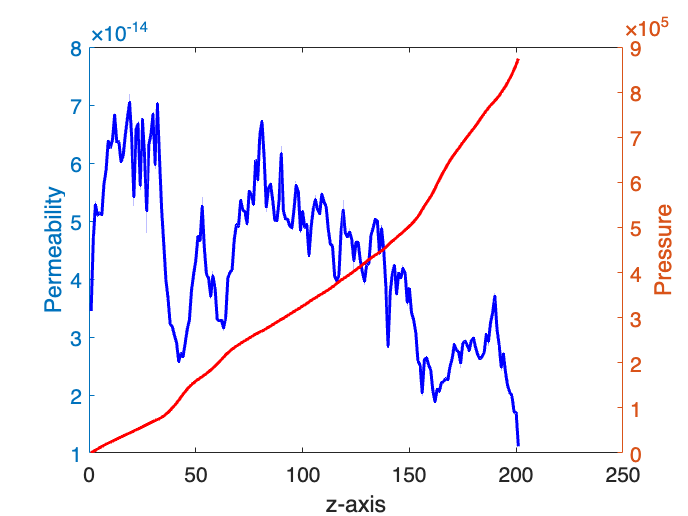


% Plot permeability and pressure
figure;
yyaxis left;
plot(k, '-b', 'LineWidth', 1.5); 
ylabel('Permeability');
xlabel('z-axis');

yyaxis right;
plot(integral_cumulative, '-r', 'LineWidth', 1.5); 
ylabel('Pressure');

## Netzwerk_nums


[uniqueVals, ~, idx] = unique([link2.label]); % Get unique values and their indices
counts = accumarray(idx, 1); % Count occurrences of each value

% Find values that appear more than 100 times
overThreshold = counts > 100; % Condition for values occurring more than 100 times
result = uniqueVals(overThreshold); % Extract values that meet the condition

% Output the number of elements that appear more than 100 times
numOver100 = sum(overThreshold); % Number of values exceeding 100 occurrences


## Netzwerk - Visualization of Channel

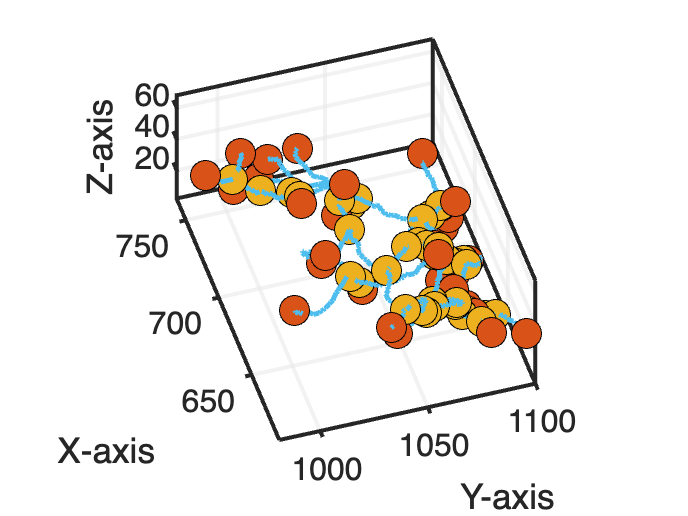


channel_label = 106; % Channel label to visualize

% Find nodes and links belonging to the selected channel
channel_nodes = find([node2.label] == channel_label);
channel_links = find([link2.label] == channel_label);

lin = link2(channel_links);
clear x1 y1 z1

% Plotting
figure();
hold on;

% Plot nodes
for i = 1:length(channel_nodes)
    node_idx = channel_nodes(i);
    x1(i) = node2(node_idx).comx;
    y1(i) = node2(node_idx).comy;
    z1(i) = node2(node_idx).comz;

    % Set color based on endpoint status
    if (node2(node_idx).ep == 1)
        ncol = "#D95319"; % Orange for endpoints
    else
        ncol = "#EDB120"; % Yellow for regular nodes
    end

    % Plot nodes in 3D
    plot3(y1(i), x1(i), z1(i), 'o', 'Markersize', 15, ...
          'MarkerFaceColor', ncol, ...
          'Color', 'k');
end

% Plot links between nodes
for i = 1:length(channel_links)
    link_idx = channel_links(i);
    points = link2(link_idx).point; % Get all voxel points of the link

    % Iterate over all voxel pairs and plot links
    for k = 1:length(points) - 1
        [x3, y3, z3] = ind2sub([w, l, h], points(k));
        [x2, y2, z2] = ind2sub([w, l, h], points(k + 1));
        line([y3 y2], [x3 x2], [z3 z2], 'Color', "#4DBEEE", 'LineWidth', 2.5);
    end
end

% Set figure and axis properties
axis image; 
set(gcf, 'Color', 'white');
ax = gca; % Get the current axes object
ax.LineWidth = 2; % Set axis line width
ax.FontName = 'Helvetica'; % Set axis font
ax.FontSize = 16; % Set font size
drawnow;
view(-17, 46); % Set viewing angle

axis on; % Turn on axis
grid on; % Display grid lines

% Label axes
xlabel('Y-axis'); 
ylabel('X-axis');
zlabel('Z-axis');

% Set grid color and transparency
set(gca, 'GridColor', [0.9, 0.9, 0.9]); % Light gray grid
set(gca, 'GridAlpha', 0.5); % Set grid transparency to 50%
zticks(0:20:max(z1));

% Enable box around the axis
ax.Box = 'on';

## Residence Time & Tou_path

### selected channel

channel_label = 3;
% Find nodes and links belonging to the selected channel
channel_nodes = find([node2.label] == channel_label);
channel_links = find([link2.label] == channel_label);

lin = link2(channel_links);
clear x1 y1 z1


% Plot nodes
for i = 1:length(channel_nodes)
    node_idx = channel_nodes(i);
    x1(i) = node2(node_idx).comx;
    y1(i) = node2(node_idx).comy;
    z1(i) = node2(node_idx).comz;
end



### Infomation for channel


% Initialize a table to store results for each channel link
result_table = table(zeros(length(channel_links), 1), ...  % Node 1 index
                     zeros(length(channel_links), 1), ...  % Node 2 index
                     zeros(length(channel_links), 1), ...  % Number of points in the link
                     cell(length(channel_links), 1), ...   % Cell array to store voxel indices
                     zeros(length(channel_links), 1), ...  % Euclidean distance between nodes
                     zeros(length(channel_links), 1), ...  % Tortuosity value
                     zeros(length(channel_links), 1), ...  % Average radius
                     cell(length(channel_links), 1), ...   % Cell array to store all radii
                     cell(length(channel_links), 1), ...   % Sv values
                     zeros(length(channel_links), 1), ...  % Weight calculation
                     'VariableNames', {'Node_1', 'Node_2', 'Num_Points', 'Points', ...
                                       'Distance', 'Tortuosity', 'Radius', 'radiuss', 'Sv', 'Gewicht'});

% Loop through each channel link
for i = 1:length(lin)
    node_1 = lin(i).n1;  % First node of the link
    node_2 = lin(i).n2;  % Second node of the link
    points = lin(i).point;  % All voxel points in the link
    num_points = length(lin(i).point);  % Number of points in the link

    % Convert linear indices to 3D coordinates
    [x, y, z] = ind2sub([w, l, h], points);
    
    % Get skeleton labels and extract unique regions
    values = Skel_label(points);
    region_idx = unique(values);
    region_idx(region_idx == 0) = [];  % Remove zero values
    Sv = Branch_stat.Sv(region_idx);  % Get Sv values for the regions
    
    % Compute radii at each voxel point
    radiuss = dist(points);
    Radius = round(sum(radiuss) / nnz(radiuss), 2);  % Compute the average radius
    
    % Compute distances between successive voxel points
    dx = diff(x); 
    dy = diff(y); 
    dz = diff(z);
    distance_matrix = sqrt(dx.^2 + dy.^2 + dz.^2); % Path length
    distance = sqrt((x(end) - x(1))^2 + (y(end) - y(1))^2 + (z(end) - z(1))^2); % Euclidean distance
    
    % Compute tortuosity (actual path length / Euclidean distance)
    tortuosity = sum(distance_matrix) / distance;

    % Compute weight (alternative: could be permeability-based)
    Gewicht = Radius.^2 / distance; % alternative:  Gewicht = distance;
    
    % Store computed values in the table
    result_table.Node_1(i) = node_1;
    result_table.Node_2(i) = node_2;
    result_table.Num_Points(i) = num_points;
    result_table.Points{i} = points;
    result_table.Distance(i) = distance;
    result_table.Tortuosity(i) = tortuosity;
    result_table.Radius(i) = Radius;
    result_table.radiuss{i} = radiuss;
    result_table.Sv{i} = Sv;
    result_table.Gewicht(i) = Gewicht;
end


% Extract the first and last voxel point from each link
Node1_Point = cellfun(@(x) x(1), result_table.Points); % First point of the link
Node2_Point = cellfun(@(x) x(end), result_table.Points); % Last point of the link

% Define the number of elements per layer (assuming 2D slices stacked in 3D)
elements_per_layer = 1201 * 1201; % Number of elements in each layer

% Compute the layer index for each node by dividing by elements_per_layer
layer_indices1 = ceil(Node1_Point / elements_per_layer); % Layer index for Node 1
layer_indices2 = ceil(Node2_Point / elements_per_layer); % Layer index for Node 2

% Add computed layer indices to the result table
result_table.layer1 = layer_indices1;
result_table.layer2 = layer_indices2;


### New Graph for Channel

% Extract the node indices from the links
s = [lin.n1]; % Start nodes
t = [lin.n2]; % End nodes

% Get unique nodes and create a mapping from original to new indices
unique_nodes = unique([s, t]); % Find unique node IDs
node_map = containers.Map(unique_nodes, 1:length(unique_nodes)); % Map old indices to new indices

% Convert old node indices to new mapped indices
s_new = arrayfun(@(x) node_map(x), s); 
t_new = arrayfun(@(x) node_map(x), t);

clear values
% Retrieve key-value pairs from the map and convert to appropriate data types
keys_original = keys(node_map);  
values_mapped = values(node_map); 

% Convert cell arrays to standard numerical arrays
keys_original = cell2mat(keys_original); 
values_mapped = cell2mat(values_mapped);  

% Create a reverse mapping from new indices back to original indices
reverse_map = containers.Map(values_mapped, keys_original);

% Assign string labels using original unique node values
node_labels = string(unique_nodes); % Use original node numbers as node names


% Identify the start and target nodes based on Z-coordinate values




### longest path

G = graph(s_new,t_new,result_table.Gewicht);
% Initialize path length variable
path_length = 1;
startNodes = find(z1 == min(z1))'; % Nodes at the lowest z-coordinate
targetNodes = find(z1 == max(z1))'; % Nodes at the highest z-coordinate

% Find the longest shortest path from start nodes to target nodes

for i = 1:length(startNodes)
    [TR, D] = shortestpathtree(G, startNodes(i), targetNodes, 'OutputForm', 'cell'); % Compute shortest paths
    [D_max, idx] = max(D); % Find the longest shortest path
    if D_max > path_length
        path_length = D_max;
        path = TR(idx); % Store the longest path
    end
end


### short path


% Construct the weighted graph using inverse of "Gewicht" as edge weights
G2 = graph(s_new, t_new, 1./result_table.Gewicht); 

% Recalculate start and target nodes based on Z-coordinates
startNodes = find(z1 == min(z1))'; 
targetNodes = find(z1 == max(z1))';

% Initialize path length variable for weighted graph
path_length2 = 1;

% Compute the longest weighted shortest path
for i = 1:length(startNodes)
    [TR, D] = shortestpathtree(G2, startNodes(i), targetNodes, 'OutputForm', 'cell'); % Compute shortest paths
    [D_max, idx] = max(D); % Find the longest shortest path
    if D_max > path_length2
        path_length2 = D_max;
        path2 = TR(idx); % Store the longest path
    end
end

### 3D Graph for path

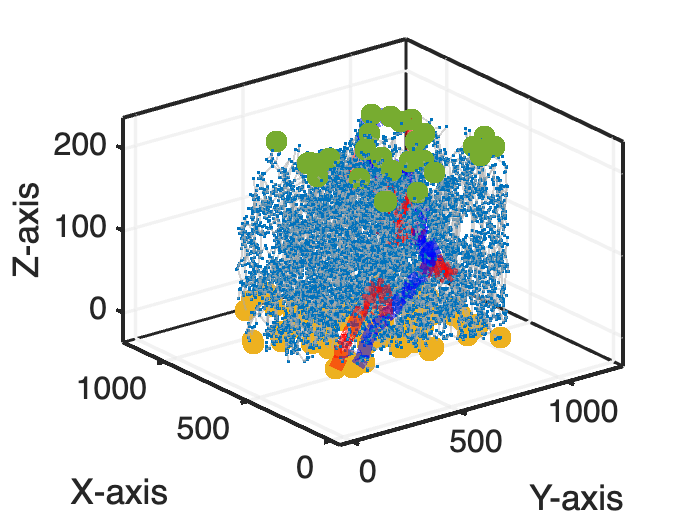

figure;
% Plot the graph in 3D space using node coordinates
p = plot(G, 'XData', x1, 'YData', y1, 'ZData', z1, 'LineWidth', 1, 'MarkerSize', 1);

% Set default edge color and transparency
p.EdgeColor = "#A9A9A9"; % Default edge color: gray
p.EdgeAlpha = 0.5; % Edge transparency

hold on;

% Highlight start and target nodes
highlight(p, startNodes, 'NodeColor', "#EDB120", 'MarkerSize', 10); % Start nodes in orange
highlight(p, targetNodes, 'NodeColor', "#77AC30", 'MarkerSize', 10); % Target nodes in green

% Highlight shortest paths
highlight(p, path{1,1}, 'EdgeColor', "#FF0000", 'LineWidth', 7); % Highlight first path in red
highlight(p, path2{1,1}, 'EdgeColor', "#0000FF", 'LineWidth', 7); % Highlight second path in blue

% Adjust figure properties
axis padded;
grid on;
axis on; % Turn on the axis

% Configure axis properties
ax = gca; % Get the current axes object
ax.LineWidth = 2; % Set axis line width
ax.FontName = 'Helvetica'; % Set font style
ax.FontSize = 16; % Set font size

% Remove node labels for a cleaner visualization
p.NodeLabel = {};

% Set background color to white
set(gcf, 'Color', 'white');

% Add axis labels
xlabel('Y-axis');
ylabel('X-axis');
zlabel('Z-axis');

% Set grid properties
set(gca, 'GridColor', [0.9, 0.9, 0.9]); % Light gray grid lines
set(gca, 'GridAlpha', 0.5); % Set grid transparency to 50%

hold off;

### Calculate


% Extract node pairs from the shortest path
%% for calculate path2 %% hier change
path_node1 = path{1}(1:end-1); % Start nodes of edges in the path
path_node2 = path{1}(2:end);   % End nodes of edges in the path

% Map back to original node indices
s_original = arrayfun(@(x) reverse_map(x), path_node1);
t_original = arrayfun(@(x) reverse_map(x), path_node2);

% Create unique node pairs
pairs = [min(s_original(:), t_original(:)), max(s_original(:), t_original(:))];

% Find matching rows in the result table for the path edges
mask = ismember([result_table.Node_1, result_table.Node_2], pairs, 'rows');
path_rows = result_table(mask, :); % Extract path-related rows

% Compute layer range for each segment of the path
path_layer = [min(path_rows.layer1(:), path_rows.layer2(:)), ...
              max(path_rows.layer1(:), path_rows.layer2(:))];

% Compute cross-sectional area of each segment
Area_branch = path_rows.Radius; % Extract radii
Area_branch = (Area_branch * 6.5e-6).^2 * pi; % Convert radius to area

% Extract distances of path segments
Distance = path_rows.Distance;

% Compute porosity along the path
porosity_1 = zeros(length(path_layer), 1);
for i = 1:length(path_layer)
    porosity_1(i) = mean(porosity(path_layer(i,1):path_layer(i,2)));
end

% Compute ratio of branch area to total area considering porosity
ratio = Area_branch./ (Area * porosity_1);

% Compute characteristic transport time (flow resistance)
t = Area_branch .* Distance * 6.5e-6 ./ (2e-6 * ratio);
total_transport_time = sum(t); % Total transport time

% Compute effective transport path length using Euclidean distance
% see start und end point!!
[x1,y1,z1] = ind2sub([1201 1201 201],388138);
[x2,y2,z2] = ind2sub([1201 1201 201],289487557);
tou = sum(Distance)/ sqrt((x2 - x1)^2 + (x2 - y1)^2 + (z2 - z1)^2);

% Compute average tortuosity along the path
mean_tortuosity = mean(path_rows.Tortuosity);

% Display results
disp(['Total Transport Time: ', num2str(total_transport_time),' s']);

Total Transport Time: 2.5468 s


disp(['Tortuosity as a result of the definition: ', num2str(tou)]);

Tortuosity as a result of the definition: 2.8707


disp(['Mean Tortuosity: ', num2str(mean_tortuosity)]);

Mean Tortuosity: 1.2425
